# Modeling Passive Solar House in Massachusetts

By Gati Aher and Zachary Sherman

All measurements are in metric

## Design Constraints

- small house

min_floor_space = 9.2903; % m^2
max_floor_space = 37.1612; % m^2

- reasonably comfortable in winter in Boston climate

min_indoor_air_temp = 17; % deg Celsius
max_indoor_air_temp = 25; % deg Celsius

- no direct sunlight through south-facing windows at noon in summer

## Minimal Implementation

### Define Materials

% use equivalent heat transfer coefficient (heq) of double-paned window
window = LiquidPureThermalResistance('double-paned window', 0.7)

window =   LiquidPureThermalResistance with properties:

                   LongName: 'double-paned window'
    HeatTransferCoefficient: 0.7000


b_storage = PureThermalStorage('recycled ceramic tile', 800, 3000)

b_storage =   PureThermalStorage with properties:

                LongName: 'recycled ceramic tile'
    SpecificHeatCapacity: 800
                 Density: 3000


b_insulation = SolidPureThermalResistance('fiberglass', 0.04)

b_insulation =   SolidPureThermalResistance with properties:

               LongName: 'fiberglass'
    ThermalConductivity: 0.0400


air_indoors = LiquidPureThermalResistance('air indoors', 15)

air_indoors =   LiquidPureThermalResistance with properties:

                   LongName: 'air indoors'
    HeatTransferCoefficient: 15


air_outdoors = LiquidPureThermalResistance('air outdoors', 30)

air_outdoors =   LiquidPureThermalResistance with properties:

                   LongName: 'air outdoors'
    HeatTransferCoefficient: 30


### Define Base Model

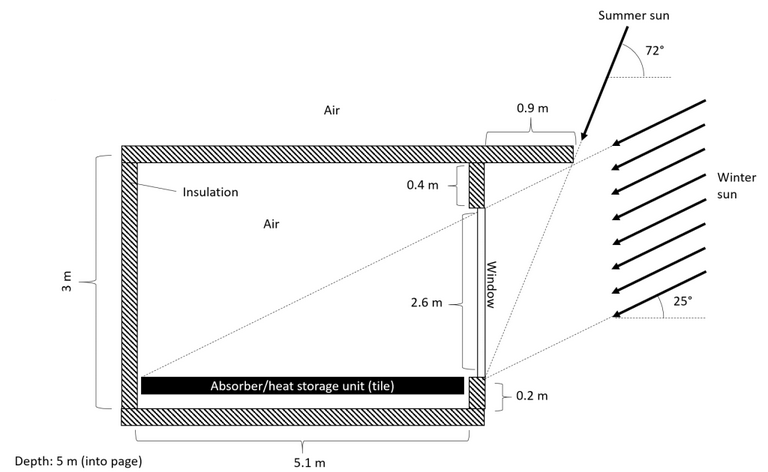

### Define Base Measurements

b_model_depth = 5;
b_model_length = 5.1;
b_model_height = 3;

% window
b_window_height = 2.4;
b_window_area = b_window_height * b_model_depth;

% storage
b_storage_thickness = 0.05;
b_storage_volume = b_model_depth * b_model_length * b_model_height;
% convection surface area
b_storage_surface_area = surfaceAreaRectPrism(b_model_depth, b_model_length, b_storage_thickness);

% insulation
b_insulation_thickness = 0.05;
% convection surface area
b_insulation_inner_surface_area = innerSurfaceAreaInsulation(b_window_area, b_model_depth, b_model_length, b_model_height, b_insulation_thickness);
b_insulation_outer_surface_area = outerSurfaceAreaInsulation(b_window_area, b_model_depth, b_model_length, b_model_height, b_insulation_thickness);

### Draw Circuit Diagram to Understand Resistance Network

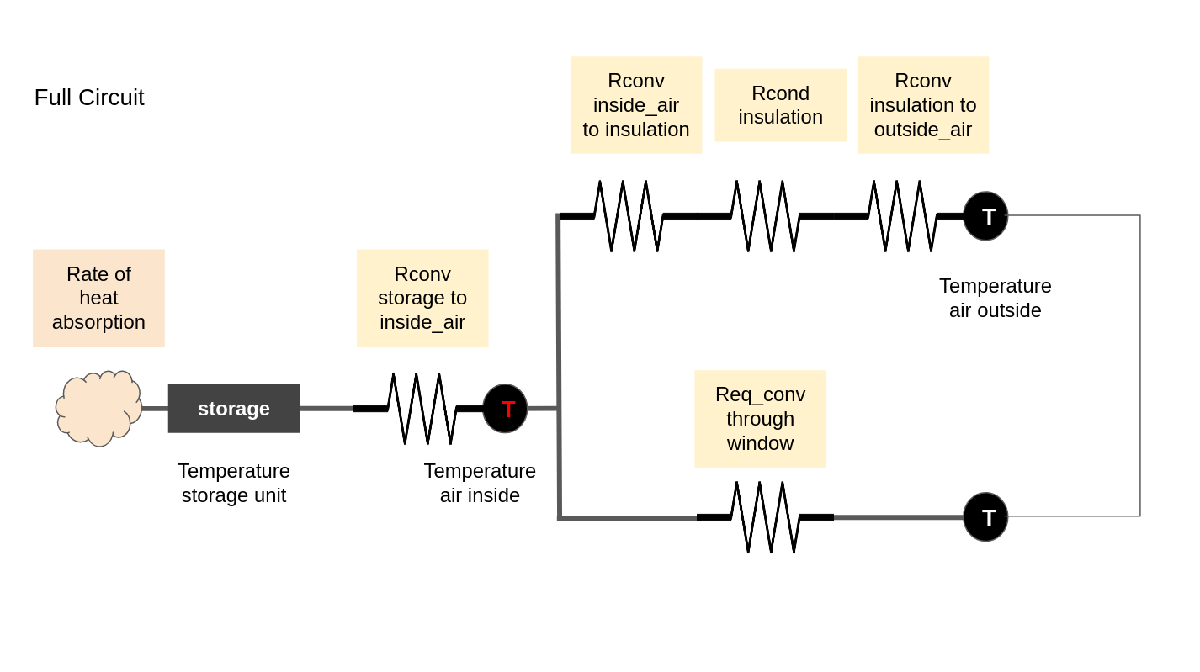

C_storage = C(b_storage, b_storage_volume);
Rconv_storage_to_inside_air = Rconv(air_indoors, b_storage_surface_area);
Rconv_inside_air_to_insulation = Rconv(air_indoors, b_insulation_inner_surface_area);
Rcond_insulation = Rcond(b_insulation, b_insulation_inner_surface_area, b_insulation_thickness);
Rconv_insulation_to_outside_air = Rconv(air_outdoors, b_insulation_outer_surface_area);
Req_conv_through_window = Rconv(window, b_window_area);

Sum resistance in series: $R_{\mathrm{totseries}} =R_1 +R_2 +\;\ldotp \ldotp \ldotp +{\;R}_n$

Rtot_through_insulation = Rconv_inside_air_to_insulation + Rcond_insulation + Rconv_insulation_to_outside_air;

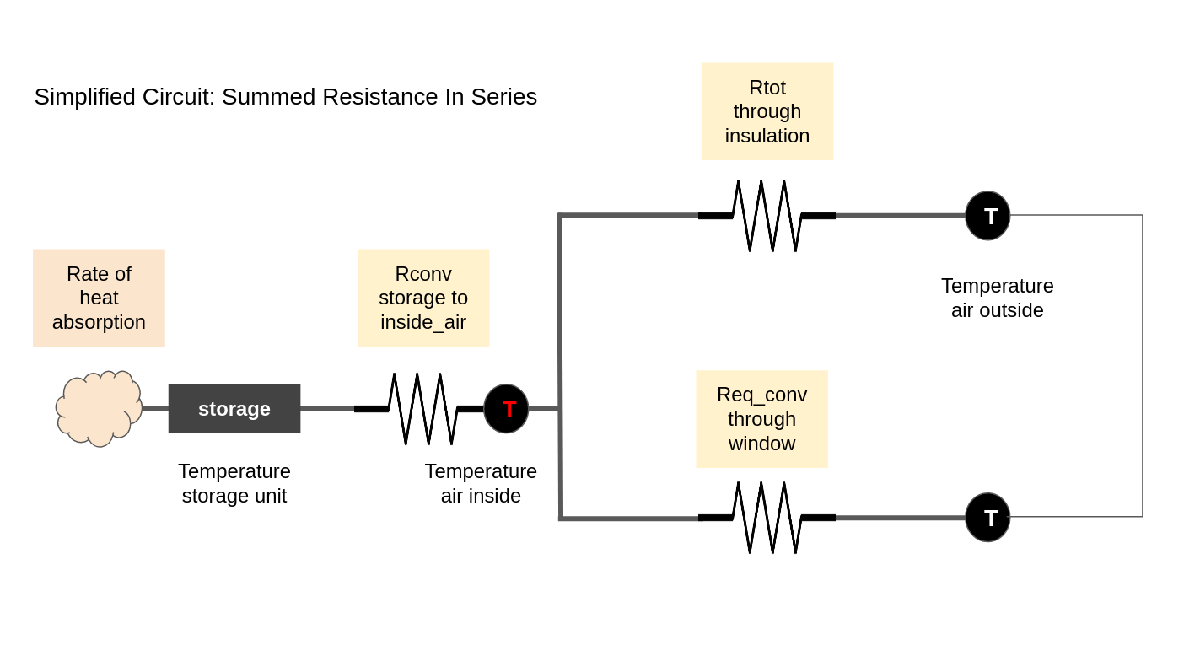

Sum the two resistances in parallel


$$R_{\mathrm{totparallel}} =\frac{R_1 \;R_2 }{R_1 +R_2 }$$


Rtot_inside_air_to_outside_air = (Rtot_through_insulation * Req_conv_through_window) / (Rtot_through_insulation + Req_conv_through_window);

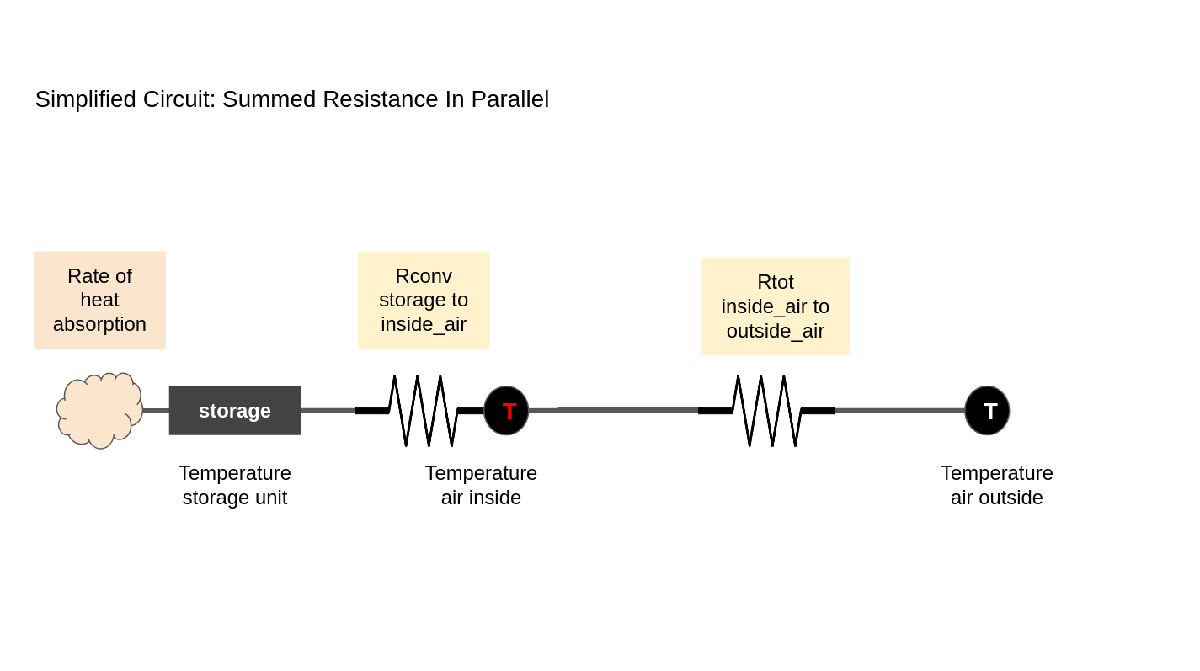

Sum in series to get resistance network in most simplified form

Rtot_storage_to_outside_air = Rconv_storage_to_inside_air + Rtot_inside_air_to_outside_air;

### 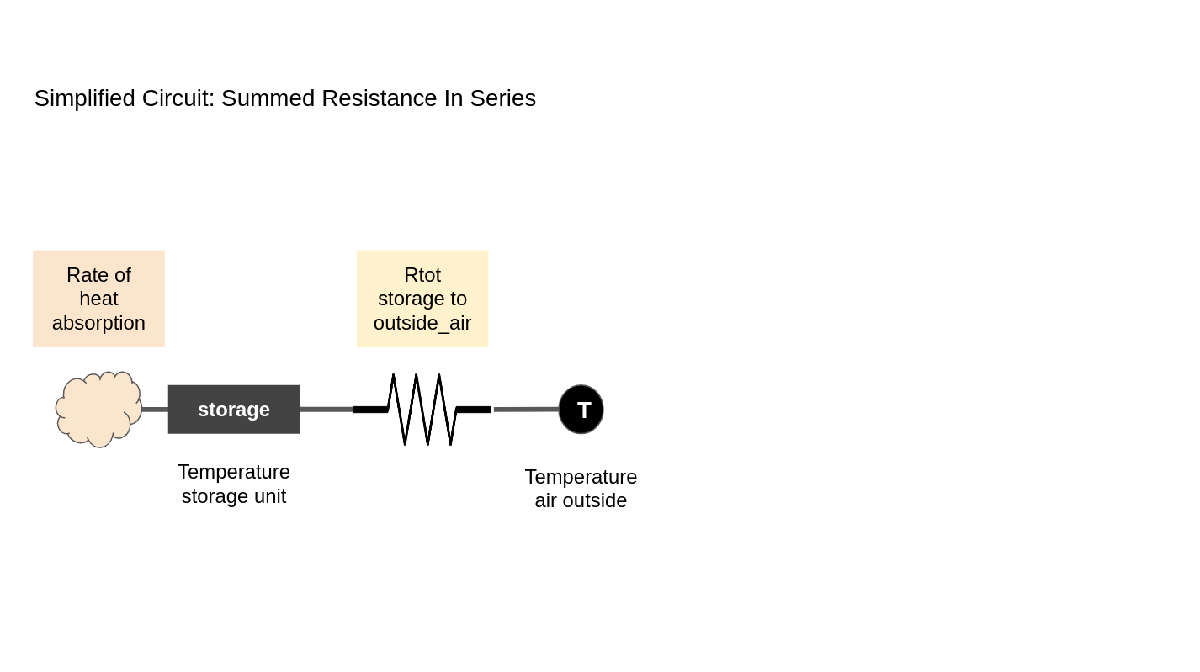

### Find a solution for the house's temperature over the course of serveral days

#### 1. Write an ordinary differential equation to model the heat storage's rate of temperature change over time.


$${\;C}_{\mathrm{storage}} \frac{{\mathrm{dT}}_{\mathrm{storage}} }{\mathrm{dt}}\;=\;\frac{{\mathrm{dU}}_{\mathrm{storage}} }{\mathrm{dt}}\;=Q\prime_{\mathrm{intostorage}} -Q\prime_{\mathrm{ourofstorage}} =Q\prime_{\mathrm{in}} \;-Q\prime_{\mathrm{out}}$$



$$Q\prime_{\mathrm{out}} =\frac{T_{\mathrm{storage}\;} -T_{\mathrm{outsideair}} }{R_{\mathrm{totstoragetooutsideair}} }$$


final ODE for $\frac{{\mathrm{dT}}_{\mathrm{storage}} }{\mathrm{dt}}$ is $y\prime$


$$y^{\prime } =\frac{\left(Q\prime_{\mathrm{in}} -\frac{y\;-T_{\mathrm{outsideair}} }{R_{\mathrm{totstoragetooutsideair}} }\right)}{C_{\mathrm{storage}} }$$


#### 2. Solve for $T_{\mathrm{insideair}}$

Heat flow through a circuit is the same for resistors in series.


$$\frac{T_{\mathrm{storage}} -T_{\mathrm{outsideair}} }{R_{\mathrm{totstoragetooutsideair}} }=\frac{T_{\mathrm{insideair}} -T_{\mathrm{outsideair}} }{R_{\mathrm{totinsideairtooutsideair}} }\;$$


By rearranging


$$T_{\mathrm{insideair}} ={T_{\mathrm{outsideair}} \;+\;R}_{\mathrm{totinsideairtooutsideair}} \frac{T_{\mathrm{storage}} -T_{\mathrm{outsideair}} }{R_{\mathrm{totstoragetooutsideair}} }\;$$
  

#### Model With Constant Outside Air Temperature

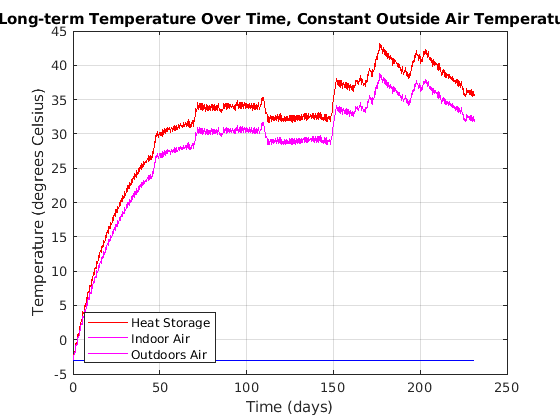

yprime_constant_outside_temp = @(t, y) (Qinprime(t, window_area) - (y - air_outside_temp_constant(t)) / Rtot_storage_to_outside_air) / C_storage;
T_storage_0 = -3;
tspan = [1 20000000];
% solve ODE for heat storage temp
[t, y] = ode45(yprime_constant_outside_temp, tspan, T_storage_0);
% solve for air temp
T_outside_air = air_outside_temp_constant(t);
T_inside_air = T_outside_air + Rtot_inside_air_to_outside_air * (y - T_outside_air) / Rtot_storage_to_outside_air;
%convert t from seconds to days for nice plots
t_days = t / (60 * 60 * 24);
plotHelper('Long-term Temperature Over Time, Constant Outside Air Temperature', t_days, 'Time (days)', y, T_inside_air, T_outside_air)

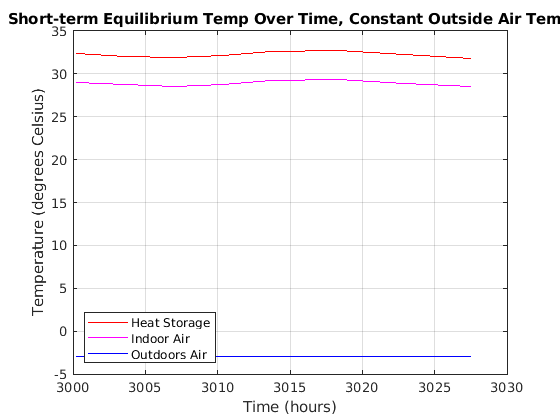

%plot temperature over course of one day at equilibrium
%convert t from seconds to hours for nice plots
t_hours = t / (60 * 60);
s = find(t_hours>3000);
s = s(1); % start 1-day period in hours
e = find(t_hours>3024); 
e = e(1); % end 1-day period in hours
plotHelper('Short-term Equilibrium Temp Over Time, Constant Outside Air Temp', t_hours(s:e), 'Time (hours)', y(s:e), T_inside_air(s:e), T_outside_air(s:e))

#### For Model With Sinusoidal Outside Air Temperature

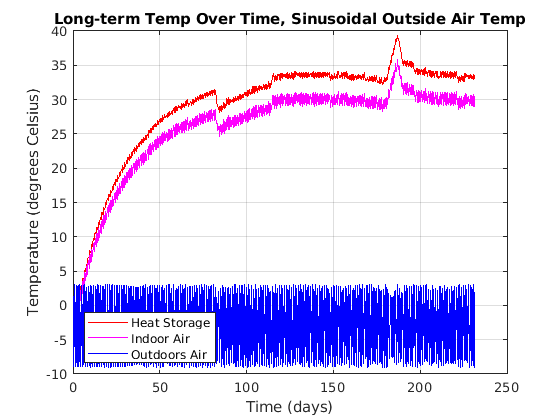

yprime_constant_outside_temp = @(t, y) (Qinprime(t, window_area) - (y - air_outside_temp_sinusoidal(t)) / Rtot_storage_to_outside_air) / C_storage;
T_storage_0 = -3;
tspan = [1 20000000];
% solve ODE for heat storage temp
[t, y] = ode45(yprime_constant_outside_temp, tspan, T_storage_0);
% solve for air temp
T_outside_air = air_outside_temp_sinusoidal(t);
T_inside_air = T_outside_air + Rtot_inside_air_to_outside_air * (y - T_outside_air) / Rtot_storage_to_outside_air;
%convert t from seconds to days for nice plots
t_days = t / (60 * 60 * 24);
plotHelper('Long-term Temp Over Time, Sinusoidal Outside Air Temp', t_days, 'Time (days)', y, T_inside_air, T_outside_air)

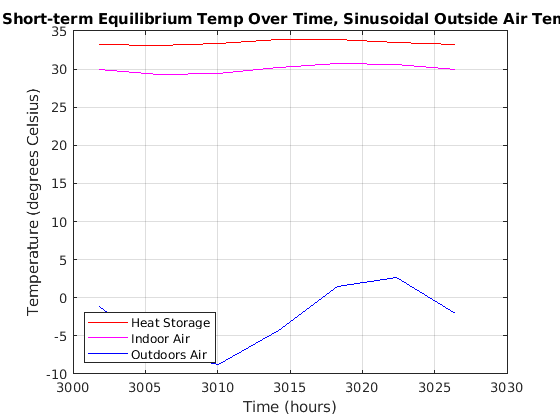

%plot temperature over course of one day at equilibrium
%convert t from seconds to hours for nice plots
t_hours = t / (60 * 60);
s = find(t_hours>3000);
s = s(1); % start 1-day period in hours
e = find(t_hours>3024); 
e = e(1); % end 1-day period in hours
plotHelper('Short-term Equilibrium Temp Over Time, Sinusoidal Outside Air Temp', t_hours(s:e), 'Time (hours)', y(s:e), T_inside_air(s:e), T_outside_air(s:e))

## Appraisal

Currently, our model predicts a house that is slightly too warm, with an equilibrium air temperature of approximately 30 °C. Although in theory, a house that is too hot is just as uncomfortable as a house that is too cold, in reality, cooling down a passive solar house is a fairly  trivial task. A smaller window could be used, the absorber's  effectiveness or surface area could be reduced, and/or the thermal mass  could be smaller. In each of these cases, this just means making the  house slightly less efficient. For our final model, we will adjust these parameters as necessary to allow for a comfortable indoor air  temperature.

#### Models of Outside Air Temperature

Outside air is a fixed potential of the system. Its value does not change due to current flowing in and out of the node from the system, so it can be modelled with a consistent function of time.

function temp = air_outside_temp_constant(t)
    %Input:
    %   t: (single column-vector of numbers) time in seconds, not used.
    %Output:
    %   temp: (single row-vector of numbers) air temperature in degrees Celsius
    temp = -3*ones(1, size(t,1));
end

function temp = air_outside_temp_sinusoidal(t)
    %Input:
    %   t: (single column-vector of numbers) time in seconds
    %Output:
    %   temp: (single row-vector of numbers) air temperature in degrees Celsius
    temp = -3 + 6 * sin(t.*((2*pi)/(24*60*60)) + (3*pi/4));
end

#### Model of $Q\prime_{\mathrm{in}}$ Heat Absorbed by the Absorber/Heat Storage Unit

To simplify the model we make the following assumptions:

- Heat storage unit is at a spatially uniform temperature

- All solar radiation hitting the window is absorbed by the heat storage unit

With these assumptions $Q\prime_{\mathrm{in}}$ can be calculated as $Q\prime_{\mathrm{in}} ={q\;A}_{\mathrm{window}}$ the product of the normal solar flux, $q$(t), and the window area, $A_{\mathrm{window}}$.

function nsf = q(t)
    %Input:
    %   t: (single row-vector of numbers) time in seconds
    %Output:
    %   nsf: (single row-vector of numbers) normal solar flux through south-facing
    %   window in Massachusetts. Units of W/m^2
    nsf = -361 * cos(t.*(pi/(12*3600))) + 244 * cos(t.*(pi/(6*3600))) + 210;
end

function heatAbsorbed = Qinprime(t,Awindow)
    %Input:
    %   t: (single row-vector of numbers) time in seconds
    %   Awindow: (number) area of window in m^2
    %Output:
    %   heatAbsorbed: (single row-vector of numbers) rate of heat absorbed by the
    %   absorber/heat storage. Units in Watts
    heatAbsorbed = q(t) .* Awindow;
end

#### Surface Area Helper Functions

function SA = surfaceAreaRectPrism(depth, length, thickness)
    %Input:
    %   depth: (number) depth of model house in meters
    %   length: (number) length of model house in meters
    %   height: (number) height of model house in meters
    %Output:
    %   SA: (number) surface area of inside of model house. Units in m^2
    SA = 2 * (depth * length + length * thickness + thickness * depth);
end

function SA = innerSurfaceAreaInsulation(window_area, depth, length, height, ~)
    %Return solid surface area that inner air convection occurs on
    %Input:
    %   Awindow: (number) area of window in m^2
    %   depth: (number) depth of model house in meters
    %   length: (number) length of model house in meters
    %   height: (number) height of model house in meters
    %Output:
    %   SA: (number) area of model house in contact with inside air. Units in m^2
    sa_total = surfaceAreaRectPrism(depth, length, height);
    SA = sa_total - window_area;
end

function SA = outerSurfaceAreaInsulation(window_area, depth, length, height, thickness)
    %Return solid surface area that outer air convection occurs on
    %Input:
    %   Awindow: (number) area of window in m^2
    %   depth: (number) depth of model house in meters
    %   length: (number) length of model house in meters
    %   height: (number) height of model house in meters
    %   thickness: (number) wall thickness in model house in meters
    %Output:
    %   SA: (number) area of model house in contact with outside air. Units in m^2
    sa_total = surfaceAreaRectPrism(depth + 2*thickness, length + 2*thickness, height + 2*thickness);
    sa = sa_total - window_area;
    % subtract area covered by overhang join
    SA = sa - ((depth + 2*thickness) * thickness);
end

#### Plotting Helper

function [] = plotHelper(plot_title, t, t_label, T_storage, T_inside_air, T_outside_air)
    % Plots Heat Storage, Indoor Air, Outdoors Air over time
    figure
    plot(t, T_storage, 'r')
    hold on
    plot(t, T_inside_air, 'm')
    plot(t, T_outside_air, 'b')
    grid on
    xlabel(t_label)
    ylabel('Temperature (degrees Celsius)')
    title(plot_title)
    legend('Heat Storage', 'Indoor Air', 'Outdoors Air', 'Location', 'southwest')
    hold off
end